# Mohammadreza Arani

## Convex Optimization

## 810100511

% Hw-8 Question 5
clear;
clc;
close all;

% Load Data:
run('treatment_planning_data.m');


cvx_begin
    variable b(n); % bj ha
        0 <= b;
        b <= Bmax;

        Atarget*b >= Dtarget % Feasibility of the problem ==> Treatment shall work
    minimize (sum(square_pos(Aother*b-Dother))) % minimize square excess dose delivered to others [non voxels]

cvx_end

 
Calling SDPT3 4.0: 2100 variables, 1000 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 1000
 dim. of sdp    var  = 800,   num. of sdp  blk  = 400
 dim. of linear var  = 900
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|1.6e+03|2.7e+01|9.6e+06| 1.413870e+05  0.000000e+00| 0:0:00| spchol  1  1 
 1|0.781|0.639|3.6e+02|9.8e+00|4.2e+06| 2.480374e+05 -9.294132e+04| 0:0:00| spchol  1  1 
 2|0.846|0.524|5.5e+01|4.7e+00|2.3e+06| 2.774105e+05 -1.451749e+05| 0:0:00| spchol  1  1 
 3|1.000|0.855|2.8e-05

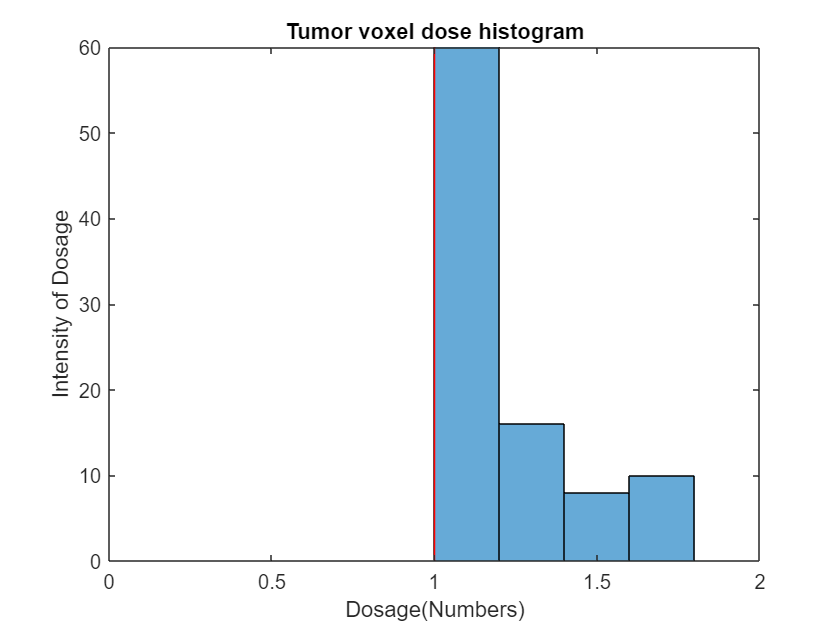

Fig1 = figure();
histogram(Atarget*b);

axis([0 2 0 60]);
hold on; 
L = 20;
plot(Dtarget*ones(1,L),linspace(0,60,L),'r'); % To darw a line 
title('Tumor voxel dose histogram');
xlabel('Dosage(Numbers)')
ylabel('Intensity of Dosage')

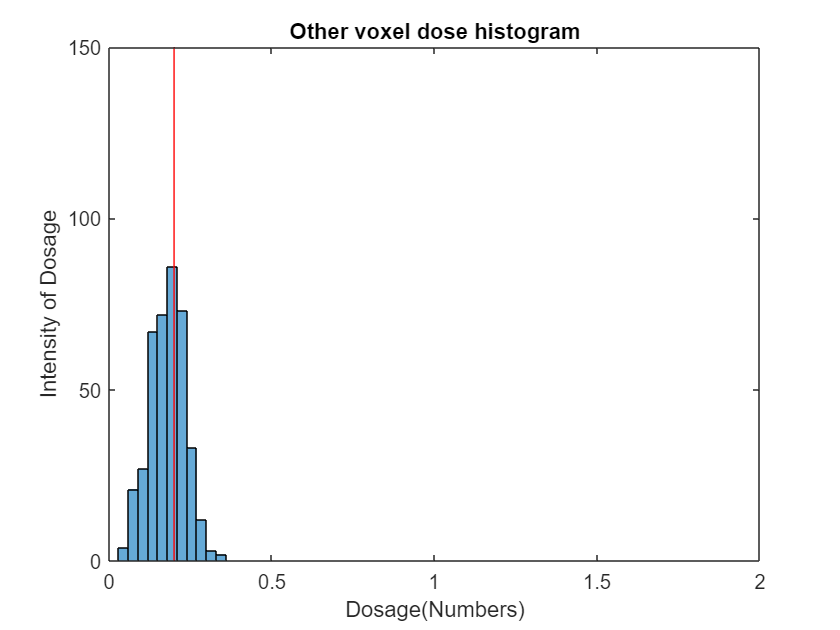

Fig2 = figure();
histogram(Aother*b);
axis([0 2 0 150]);
hold on; 
plot(Dother*ones(1,L),linspace(0,150,L),'r'); % To darw a line
title('Other voxel dose histogram')
xlabel('Dosage(Numbers)')
ylabel('Intensity of Dosage')